# Hands On: State Space Descriptions

## Introduction

This live script illustrates some models of dynamical systems (linear or nonlinear, time-invariant or time-variant, continuous or discrete time). 

Inspired by the examples illustrated in the live script [StateSpaceDescriptionExamples.mlx](matlab:open('./StateSpaceDescriptionExamples.mlx')), you  will able to create a Matlab live script and a Simulink model working together in order to simulate the behavior of a continuous time or discrete time dynamical system.

What you will learn: 

- Given a state space description of a dynamical system, how to build a Simulink model for such a system;

- Tune a Simulink model, setting the model parameters (or the simulation parameters) using a Matlab script;

- How to run a Simulink model and retrieve the results using a Matlab script.

## A Linear Continuous Time System: a Mechanical System

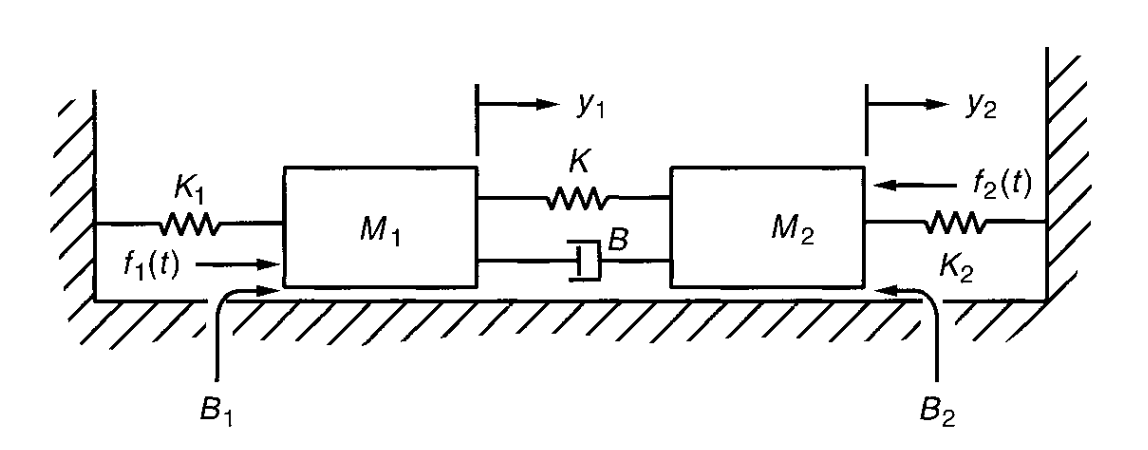

 The dynamics of the system is given by the state-space model derived from conservation balances (of mass, energy, etc.). Applying Newton's second law, we obtain the following state-space description:


$$\left\{ \begin{array}{lcl}
\left[ \begin{array}{c}
\dot{x}_1(t) \\ \dot{x}_2(t) \\ \dot{x}_3(t) \\ \dot{x}_4 (t)
\end{array} \right] &=& \left[ \begin{array}{cccc} 
0 & 1 & 0 & 0 \\[0.5em]
-\displaystyle \frac{K_1+K}{M_1} & -\displaystyle \frac{B_1+B}{M_1} & \displaystyle \frac{K}{M_1} & \displaystyle \frac{B}{M_1} \\[0.5em]
0 & 0 & 0 & 1 \\[0.5em]
 \displaystyle \frac{K}{M_2} & \displaystyle \frac{B}{M_2} &-\displaystyle \frac{K_2+K}{M_2} & -\displaystyle \frac{B_2+B}{M_2}
\end{array} \right] \, \left[ \begin{array}{c}
x_1(t) \\ x_2(t) \\ x_3(t) \\ x_4 (t)
\end{array} \right] \, + \, 
\left[ \begin{array}{cc}
0 & 0 \\[0.5em]
\displaystyle \frac{1}{M_1} & 0 \\[0.5em]
0 & 0 \\[0.5em]
0 & \displaystyle -\frac{1}{M_2} 
\end{array} \right] \, \left[ \begin{array}{c}
f_1(t) \\[0.5em]
f_2(t) 
\end{array} \right] \\[0.75em] \\
\left[ \begin{array}{c}
y_1(t) \\[0.5em]
y_2(t) 
\end{array} \right] &=& \left[ \begin{array}{cccc}
1 & 0 & 0 &0\\[0.5em]
0 & 0 & 1 & 0
\end{array} \right] \, \left[ \begin{array}{c}
x_1(t) \\ x_2(t) \\ x_3(t) \\ x_4 (t)
\end{array} \right] 
\end{array} \right.$$


where the state variables are


$$\left\{ \begin{array}{lcl}
x_1(t) &=& y_1(t) \\
x_2(t) &=& \dot{y}_1(t) \\
x_3(t) &=& y_2(t) \\
x_4(t) &=& \dot{y}_2(t)
\end{array} \right.$$


This state-space description may be easily implemented in Matlab/Simulink.

**Proposal**: implement a Simulink model and a Matlab live script to analyse the evolution of the above described mechanical system. Use the following parameters to configure tthe system model:

- point masses [kg]: $M_1 = 1.0$ , and $M_2 = 2.5$;

- viscous damping coefficients [N s/m]: $B = 3.60 \cdot 10^{-3}\, , \quad B_1 = 5.0 \cdot 10^{-2}\, , \quad B_2 = 5.0 \cdot 10^{-2}\$;

- spring constants [N/m] : $K = 9.1 \cdot 10^{-2}\, , \quad K_1 = 1.0 \cdot 10^{-1}\, , \quad K_2 = 1.0 \cdot 10^{-1}$;

- initial conditions: $x(0) = \left[ \begin{array}{cccc} 1.0 & 0 & -0.5 & 0 \end{array} \right]^{T}$

- external forces (inputs): $f_1(t) = 2 \cdot 1(t) \;, \quad f_2(t) = -2 \cdot 1(t-10)$

- simulation time interval [s]: $t \in \left[ 0 \, , 30\right]$

% Create a state-space description using a Simulink model, then using 
% a Matlab live script assign the model parameters, the initial state,
% the simulation configuration. 
% Using the same live script, run the Simulink model, retrieve the result
% and plot the state and output movements.

close all
clear
clc

M1 = 1;
M2 = 2.5;
B = 3.6e-3;
B1 = 5e-2;
B2 = 5e-2;
K = 9.1e-2;
K1 = 1e-1;
K2 = 1e-1;

x0 = [1 0 -0.5 0]';

s = tf('s'); % s because is continuous
t = (0:0.1:30);

f = zeros(2,301);
f(1,:) = 2;
f(2,100:end) = -2;


A = [0 1 0 0;
     -(K1+K)/M1  -(B1+B)/M1 K/M1 B/M1;
     0 0 0 1;
     K/M2 B/M2 -(K2+K)/M2 -(B2+B)/M2];

B =[0 0;
    1/M1 0;
    0 0;
    0 -1/M2];

C = [1 0 0 0; 0 0 1 0];

D = 0;

LTI_C_sys = ss(A, B, C, D);
TF_LTI_C_sys = tf(LTI_C_sys);

response = lsim(LTI_C_sys, f, t);

%plot(t, response(:,1), '-', 'LineWidth', 2, 'Color', [0.9290 0.6940 0.1250]);
%xlabel('time');
%grid on; 
%legend('y1_t', 'Location','best');
%plot(t, response(:,2), '-', 'LineWidth', 2);
%xlabel('time');
%grid on; 
%legend('y2_t', 'Location','best');

plot(t, response(:,1), '-', t, response(:,2), '-', 'LineWidth', 2);
xlabel('time');
grid on; 
legend('x1', 'x3', 'Location','best');

## A Linear Discrete Time System: a Supply Chain System

The dynamics of the system is given by the state-space model derived from conservation balances (of mass, energy, etc.). 

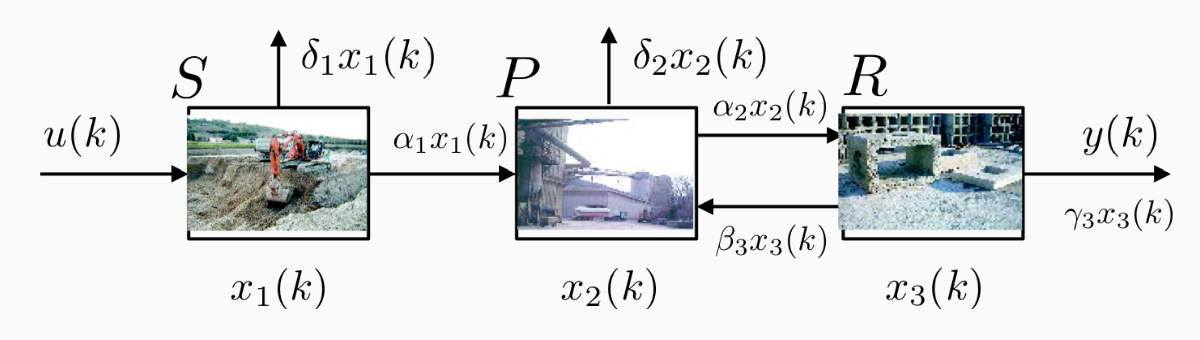

- $S$purchases the quantity $u(k)$ of raw material at each month $k$;

- A fraction $\delta_1$of raw material is discarded; a fractiion $\alpha_1$ is shipped to producer $P$;

- A fraction $\alpha_2$ of product is sold by $P$ to retailer $R$, a fraction $\delta_2$ is discarded;

- Retailer $R$returns a fraction $\beta_3$ of defective products every month, and sells a fraction $\gamma_3$to customers.

Paying attention to the material flow in each work step, we obtain the following description:


$$\left \{
\begin{array}{l}
x_1 (k+1) = (1 - \alpha_1 - \delta_1) x_1 (k) + u(k)\\
x_2 (k+1) = \alpha_1 x_1 (k) + (1-\alpha_2 - \delta_2) x_2 (k) + \beta_3 x_3 (k) \\
x_3 (k+1) = \alpha_2 x_2 (k) + (1 - \beta_3-\gamma_3) x_3 (k) \\
y(k) = \gamma_3 x_3 (k)
\end{array}
\right . 
$$
 

where

- $k \quad \Longleftrightarrow \quad$month counter

- $x_1(k) \quad \Longleftrightarrow \quad$raw material in $S
$

- $x_2(k) \quad \Longleftrightarrow \quad$products in $P$

- $x_3(k) \quad \Longleftrightarrow \quad$products in $R$

- $y(k)  \quad \Longleftrightarrow \quad$products sold to customers

The following constraints apply to the model parameters

 $\begin{array}{c}
0 < \alpha_1 \le1 \\
0 \le \delta_1 <1 \\
0 < \alpha_2 \le 1 \\
0 \le \delta_2 <1 \\
0 \le \beta_3 < 1 \\
0 < \gamma_3 \le 1
\end{array}$   and   $\begin{array}{c}
0 < \alpha_1+\delta_1 \le 1 \\
0< \alpha_2+\delta_2 \le 1 \\
0< \beta_3+\gamma_3 \le 1
\end{array}$

**Proposal**: create a Simulink model and a Matlab live script to analyse the evolution of this discrete time dynamical system. Use the following parameters to configure tthe system model:

- choose random values for the system parameters $\alpha_1\,,\; \alpha_2\,,\; \delta_1\,,\; \delta_2\,,\; \beta_3\,,\; \gamma_3$, ensuring that constraints on the parameters are respected;

- assuming that $x_1$,  $x_2$ and  $x_3$ can take on non-integer values, choose for the initial state three random values in the range $\big[ 100.0\, , \; 500.0 \big]$;

- input of raw material: $u(k) = 75\cdot 1(k) +35\sin\big(6k \big) \cdot 1(k)$

- simulation time interval [months]: $t \in \left[ 0 \, , 36\right]$

% Create a state-space description using a Simulink model, then using 
% a Matlab live script assign the model parameters, the initial state,
% the simulation configuration. 
% Using the same live script, run the Simulink model, retrieve the result
% and plot the state and output movements.

## A Linear Discrete Time System: a linear Finite Difference Equation

The state-space model is derived from a difference equation model (an Input/Output model):


$$y(k)-3 y(k-1)+2y(k-2)-y(k-3) = 6 u(k)$$


Letting


$$\left \{
\begin{array}{l}
x_1(k) := y(k-3) \\
x_2(k) := y(k-2) \\
x_3(k) := y(k-1)
\end{array}
\right . $$


one gets:


$$\left \{
\begin{array}{l}
x_1(k+1) = x_2(k) \\
x_2(k+1) = x_3(k) \\
x_3(k+1) = 3 x_3(k) - 2 x_2(k) + x_1(k) + 6 u(k) \\
y(k) = 3 x_3(k) - 2 x_2(k) + x_1(k) + 6 u(k)
\end{array}
\right .$$


**Proposal**: create a Simulink model and a Matlab live script to analyse the evolution of this discrete time dynamical system. Use the following parameters to configure tthe system model:

- choose random values for the initial state $\big[ x_1(0)\,,\; x_2(0)\, ,\; x_3(0) \big]^T$

- assuming as input the sequence: $u(k) = 1.25\cdot 1(k) +\displaystyle \Big(-\frac{2}{3}\Big)^{k} \cdot 1(k)$

- simulation time interval: $t \in \left[ 0 \, , 25\right]$

% Create a state-space description using a Simulink model, then using 
% a Matlab live script assign the model parameters, the initial state,
% the simulation configuration. 
% Using the same live script, run the Simulink model, retrieve the result
% and plot the state and output movements.

close all;
clear;
clc;


x_0 = rand(3, 1);
open_system("HandOn_SSD_3");

T_start = 0;
T_stop = 25;

simOut = sim("HandOn_SSD_3.slx");
data = simOut.get("yout");

y1 = data(:, 1);
u1 = data(:, 2);
t = simOut.get("tout");

stem(t, y1);
grid("on");
stem(t, u1);
grid("on");